clc; clearvars;

tempo_path = "C:\NERTO_drive\TEMPO_data";
tropomi_path = "C:\NERTO_drive\TROPOMI_data";
merged_path = "C:\NERTO_drive\merged_data_ams";

tempo_files = tempo_table(tempo_path);
tropomi_files = tropomi_table(tropomi_path);
merged_files = merged_table(merged_path);

process = true;
overwrite = true;

lat_bounds = [40.5 41];
lon_bounds = [-74.3 -73.65];

run_day = datetime("2024-08-01", "InputFormat", "uuuu-MM-dd"); run_day.TimeZone = "UTC"; % may have to change this to east coast

% comment out disp messages in function or add clc
if process == true
    merge_no2(run_day, lat_bounds, lon_bounds, tempo_path, tropomi_path, merged_path, overwrite_on=overwrite);
end

Processing data for 01-Aug-2024
Loading all Tropomi data
Loading all Tempo data
Creating observation error covariance matrix
Creating background error covariance matrix
Creating correlation matrix
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
Calculating observation matrix
Calculating Kalman Gain matrix
Calculating analysis update
Saving data
100 %
TEMPO_TROPOMI_merged_20240801_S5.nc saved
TEMPO_TROPOMI_merged_20240801_S6.nc saved
TEMPO_TROPOMI_merged_20240801_S7.nc saved
TEMPO_TROPOMI_merged_20240801_S8.nc saved
TEMPO_TROPOMI_merged_20240801_S9.nc saved
TEMPO_TROPOMI_merged_20240801_S10.nc saved
TEMPO_TROPOMI_merged_20240801_S11.nc saved
TEMPO_TROPOMI_merged_20240801_S12.nc saved



Plot tempo, tropomi, and merged data

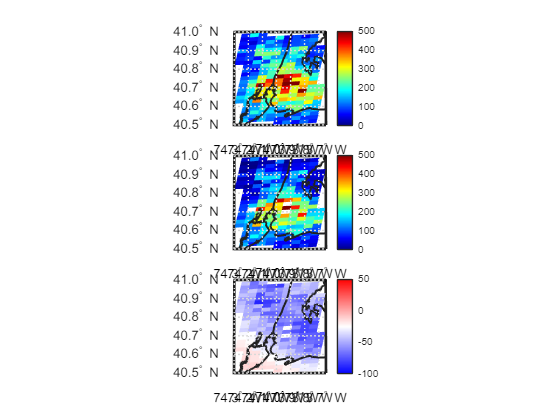

US_states = readgeotable('cb_2023_us_state_500k.shp');
lw = 1.5;
font_size = 30;
resolution = 300;
USA = load("./misc/USA.mat");
USA = USA.USA;

merged_files = merged_files(merged_files.Date>=run_day & merged_files.Date<run_day+days(1),:);
tempo_files = tempo_files(tempo_files.Date>=run_day & tempo_files.Date<run_day+days(1),:);
tropomi_files = tropomi_files(tropomi_files.Date>=run_day & tropomi_files.Date<run_day+days(1),:);

scans = intersect(unique(tempo_files.Scan), unique(merged_files.Scan));

mode = "single_scan";
scan_to_plot = scans(3);

color_lim_mode = "auto";
color_lim_no2 = [0 500];
color_lim_diff = [-100 50];

if mode == "single_scan"
    tiledlayout(3,1)

    [tempo_lat,tempo_lon,tempo_no2] = concate_tempo_scan(tempo_files,scan_to_plot);
    tempo_no2 = tempo_no2 .* 10^6 ./ conversion_factor('trop-tempo');

    nexttile;
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(tempo_lat,tempo_lon,tempo_no2);
    geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    colorbar;
    ax = gca;
    ax.CLim = color_lim_no2;
    colormap(gca,'jet');


    merged_file = merged_files(merged_files.Scan == scan_to_plot,:);
    merged_lat = ncread(merged_file.Filename, "/geolocation/latitude");
    merged_lon = ncread(merged_file.Filename, "/geolocation/longitude");
    merged_no2 = ncread(merged_file.Filename, "/product/vertical_column_troposphere") .* 10^6;

    nexttile;
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(merged_lat,merged_lon,merged_no2);
    geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    colorbar;
    ax = gca;
    ax.CLim = color_lim_no2;
    colormap(gca,'jet');


    no2_diff = merged_no2 - tempo_no2;
    nexttile;
    usamap(lat_bounds, lon_bounds);
    hold on;
    surfm(merged_lat,merged_lon,no2_diff);
    geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
    hold off;
    cb = colorbar;
    ax = gca;
    ax.CLim = color_lim_diff;
    colormap(gca,USA);

    % set(gcf, 'WindowState', 'Maximized')


elseif mode == "full_day"
    tiledlayout(2, length(scans));

    for i = 1:length(scans)
        scan = scans(i);
        [tempo_lat,tempo_lon,tempo_no2] = concate_tempo_scan(tempo_files,scan);
    
        nexttile(i);
        usamap(lat_bounds, lon_bounds);
        hold on;
        surfm(tempo_lat,tempo_lon,tempo_no2);
        geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
        hold off;

        merged_file = merged_files(merged_files.Scan == scan,:);
        merged_lat = ncread(merged_file.Filename, "/geolocation/latitude");
        merged_lon = ncread(merged_file.Filename, "/geolocation/longitude");
        merged_no2 = ncread(merged_file.Filename, "/product/vertical_column_troposphere");
    
        nexttile(length(scans)+i);
        usamap(lat_bounds, lon_bounds);
        hold on;
        surfm(merged_lat,merged_lon,merged_no2);
        geoshow(US_states, "DisplayType", "polygon", 'FaceAlpha', 0, 'LineWidth', lw);
        hold off;
        
        % break % remove later
    end
end

function [full_lat, full_lon, full_no2] = concate_tempo_scan(tempo_files, scan)
    tempo_dim = [2048, 1400];
    tempo_files = tempo_files(tempo_files.Scan==scan,:);
    tempo_files = sortrows(tempo_files, "Granule", "ascend");

    full_lat = NaN(tempo_dim);
    full_lon = NaN(tempo_dim);
    full_no2 = NaN(tempo_dim);

    for i = 1:height(tempo_files)
        mirror_step = ncread(tempo_files.Filename(i), "/mirror_step");
        temp_lat = ncread(tempo_files.Filename(i), "/geolocation/latitude");
        temp_lon = ncread(tempo_files.Filename(i), "/geolocation/longitude");
        temp_no2 = ncread(tempo_files.Filename(i), "/product/vertical_column_troposphere");

        full_lat(:,mirror_step+1) = temp_lat;
        full_lon(:,mirror_step+1) = temp_lon;
        full_no2(:,mirror_step+1) = temp_no2;
    end
end